clear;
n=2;
coordinate=sym("u%d",[n,1]);

g=[1/(coordinate(2)^2),0;0 ,1/(coordinate(2)^2)];
%Hyperbolic space
uinterval=[-5,5];
vinterval=[0,2*pi];
hh=hjs("n",n,"coordinate",coordinate,"X",coordinate,"g",g);
hh();
hh.g

$$ans = \left(\begin{array}{cc} \frac{1}{{u_{2}}^{2}} & 0\\ 0 & \frac{1}{{u_{2}}^{2}} \end{array}\right)$$

hh.connection

$$\left(\begin{array}{cc} 0 & -\frac{1}{u_{2}}\\ \frac{1}{u_{2}} & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} -\frac{1}{u_{2}} & 0\\ 0 & -\frac{1}{u_{2}} \end{array}\right)$$

hh.curvature_tensor();
hh.Scalar_curvature

$$ans = -2$$

hh.Gauss_curvature

$$ans = -1$$

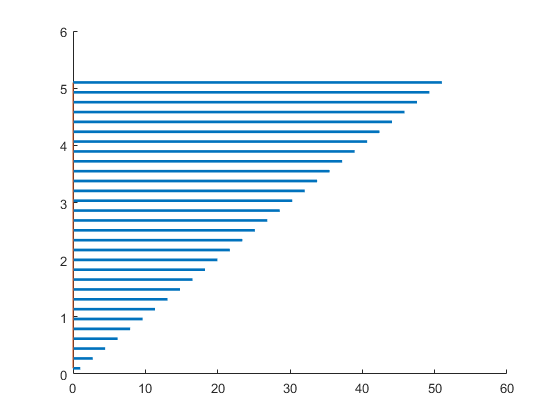

Y =     1.0000    2.7241    4.4483    6.1724    7.8966    9.6207   11.3448   13.0690   14.7931   16.5172   18.2414   19.9655   21.6897   23.4138   25.1379   26.8621   28.5862   30.3103   32.0345   33.7586   35.4828   37.2069   38.9310   40.6552   42.3793   44.1034   45.8276   47.5517   49.2759   51.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hh.drawmesh(uinterval,vinterval,0);
hold on;
syms t;
u(t)=[0;0.1+t];
hh.scale=0;
Y=hh.parallel_transport(u,[0,5],[1,0],30)

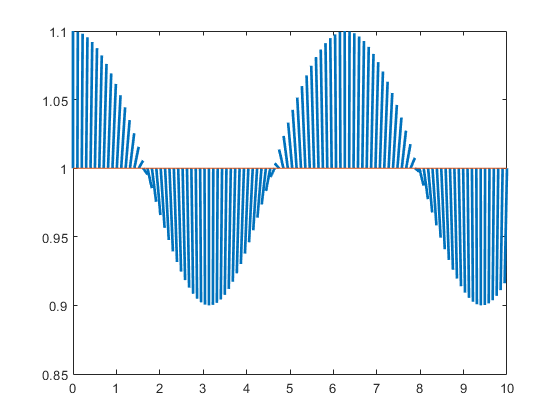

u(t)=[t;1];
hh.scale=0;
figure;
Y=hh.parallel_transport(u,[0,10],[0,0.1],100);

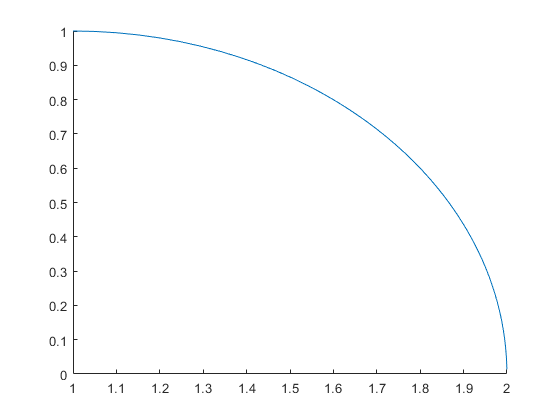

% length=reshape(Y,2,1,[]).*reshape(Y,1,2,[]).*hh.g
figure;
hh.drawmesh(uinterval,vinterval,0);
hold on;
hh.geodesic([0,5],[0,1, 1, 1],100);